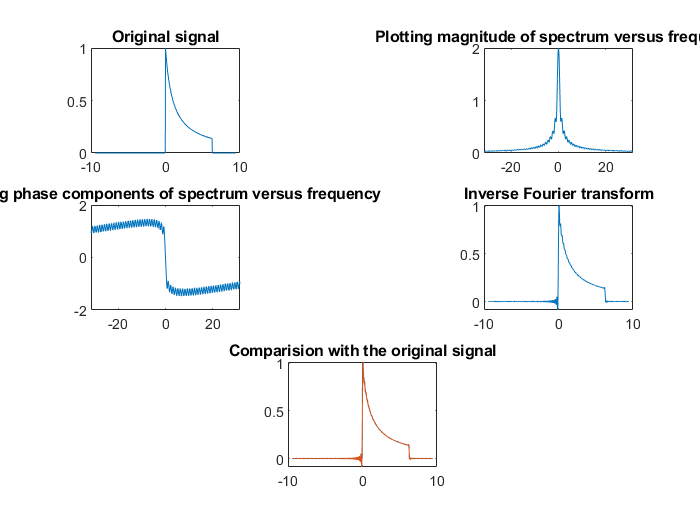

clear
clc
close all

w=-10*pi:0.01*pi:10*pi;
t=-3*pi:0.01*pi:3*pi;
% PROBLEM 3
b=zeros(size(t));
for i=1:length(t)
    t1=t(i);
    k=1+abs(t1);
    b(i)=1/k;
end    
x=b.*(unit(t)-unit(t-2*pi));
subplot(3,3,1);plot(t,x);title('Original signal');

x_w=zeros(size(w));
for i=1:length(w)
    k=w(i);
    basis1=exp(-1i*k*t);
    x_w(i)=trapz(t,x.*basis1);
end 
subplot(3,3,3);plot(w,abs(x_w));
title('Plotting magnitude of spectrum versus frequency');
subplot(3,3,4);plot(w,angle(x_w));
title('Plotting phase components of spectrum versus frequency');

x_t=zeros(size(t));
for i=1:length(t)
    k=t(i);
    basis2=exp(1i*w*k);
    x_t(i)=(1/(2*pi))*trapz(w,x_w.*basis2);
end    
subplot(3,3,6);plot(t,real(x_t));title('Inverse Fourier transform');
subplot(3,3,8);plot(t,x);
hold on;
plot(t,real(x_t));title('Comparision with the original signal');